**The simulations of mRNA buffering during cell growth.**

**For Figure 3b, c, d, and S5.**

mRNA production rate increases sublinearly with the cell volume (Figure 3c and S5)

%Basic paramters
load ../Parameter_determination/Basic_parameters.mat

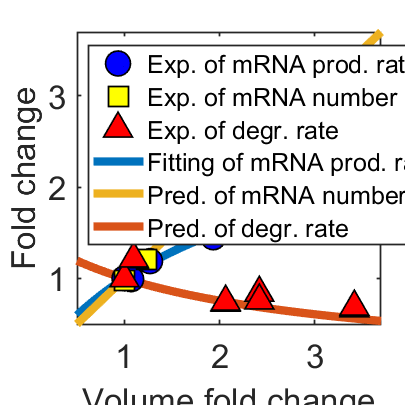

syms k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv
para_sym=[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv];

% Symbolic solutions
load ../Solve_values/Solve_values.mat
syms_solve=[Xn_pre,Xc_pre,Xp_pre,Yn_pre,Yp_pre];


%Modify the basic parameters
k0=para_opt(1)/3;
am=para_opt(5);
ax=para_opt(6);
ay=para_opt(7);
bx=para_opt(9);
bm=para_opt(8);
Kx=para_opt(2);
Km=para_opt(4);
Vn=2.8;
Vc=37.2;
Kv=5.8262;
Ky=para_opt(3);
Xt=para_opt(10);
Yt=para_opt(11);

Vn_wt=Vn;
Vc_wt=Vc;

nperm=500;%number of simulations

% Change the cell size
Vn_ori=[linspace(Vn/10,Vn,nperm/2-1),Vn,linspace(Vn,Vn*3.8,nperm/2)];
Vc_ori=[linspace(Vc/10,Vc,nperm/2-1),Vc,linspace(Vc,Vc*3.8,nperm/2)];

% Keep the concentration of X and Y constant
temp_ratio=Vn_ori/Vn_wt;
Xt_ori=Xt*temp_ratio;
Yt_ori=Yt*temp_ratio;


%simulations
mn_tot=zeros(1,nperm);
mc_tot=zeros(1,nperm);
Xn_tot=zeros(1,nperm);
Xc_tot=zeros(1,nperm);
Xp_tot=zeros(1,nperm);
Yn_tot=zeros(1,nperm);
Yp_tot=zeros(1,nperm);

vpro_tot=zeros(1,nperm);
vexp_tot=zeros(1,nperm);
vdeg_tot=zeros(1,nperm);

parfor j=1:nperm

    Xt=Xt_ori(j);
    Yt=Yt_ori(j);
    Vn=Vn_ori(j);
    Vc=Vc_ori(j);

    para0=[k0 Kx Ky Km am ax ay bm bx Xt Yt];
    para_num=[para0,Vn,Vc,Kv];
    %para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]

    temp1=double(subs(syms_solve,para_sym,para_num));% Xn Xc Xp Yn Yp
    temp1=temp1(~any(temp1<0,2),:);
    temp2=[Vn*para0(7)/para0(5),Vc*para0(9)/para0(8)];% mn mc
    y_res=[temp2,temp1]; %[mn mc Xn Xc Xp Yn Yp]

    Xp=y_res(5);
    Yp=y_res(7);
    mn=y_res(1);
    vpro=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

    Yn=y_res(6);
    mn=y_res(1);
    vexp=am*Yn*mn/Vn;

    Xc=y_res(4);
    mc=y_res(2);
    vdeg=bm*Xc*mc/Vc;


    mn_tot(j)=mn;
    mc_tot(j)=mc;
    Xn_tot(j)=y_res(3);
    Xc_tot(j)=y_res(4);
    Xp_tot(j)=y_res(5);
    Yn_tot(j)=y_res(6);
    Yp_tot(j)=y_res(7);

    vpro_tot(j)=vpro;
    vexp_tot(j)=vexp;
    vdeg_tot(j)=vdeg;
end


%plot (Figure 3b)
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];
V_tot=Vn_ori+Vc_ori;
m_tot=mn_tot+mc_tot;
alpha=vdeg_tot./mc_tot;

%Data
Data_Swaffer2021_V_mRNA=readmatrix('../Data/Data_Swaffer2022_V.xlsx','sheet','mRNA');
Data_Swaffer2021_V_occ=readmatrix('../Data/Data_Swaffer2022_V.xlsx','sheet','occ');
Data_Swaffer2021_V_decay=readmatrix('../Data/Data_Swaffer2022_V.xlsx','sheet','decay');

wt=find(Vn_ori==Vn_wt);
wt=wt(2);

fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);


p1=plot(V_tot/V_tot(wt),vpro_tot/vpro_tot(wt),'-', ...
    "LineWidth",5, ...
    "Color",colors(1),...
    "DisplayName","Fitting of mRNA prod. rate");
hold on
p2=plot(V_tot/V_tot(wt),m_tot/m_tot(wt),'-',...
    "LineWidth",5, ...
    "Color",colors(3),...
    "DisplayName","Pred. of mRNA number");
hold on
p3=plot(V_tot/V_tot(wt),alpha/alpha(wt),'-',...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Pred. of degr. rate");
hold on
p4=plot(Data_Swaffer2021_V_occ(:,3),Data_Swaffer2021_V_occ(:,2), ...
    'o', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",1,...
    "MarkerFaceColor",colors(10), ...
    "DisplayName","Exp. of mRNA prod. rate");
hold on
p5=plot(Data_Swaffer2021_V_mRNA(:,3),Data_Swaffer2021_V_mRNA(:,2), ...
    's', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",1,...
    "MarkerFaceColor",colors(13), ...
    "DisplayName","Exp. of mRNA number");
hold on
p6=plot(Data_Swaffer2021_V_decay(:,4),Data_Swaffer2021_V_decay(:,2), ...
    '^', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",1,...
    "MarkerFaceColor",colors(8), ...
    "DisplayName","Exp. of degr. rate");
hold off
xlim([0.5,3.7])
ylim([0.5,3.7])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p4 p5 p6 p1 p2 p3],"Interpreter","tex","FontSize",15,'Location','northwest')
xlabel('Volume fold change','interpreter','tex','FontSize',20);
ylabel('Fold change','interpreter','tex','FontSize',20);


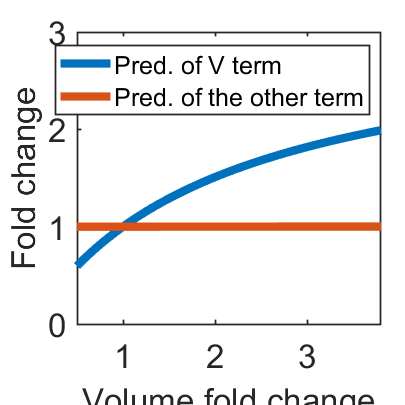



% Plot of the volume dependence
% of the two terms in kn. (Figure S5)

%the V-term in kn
kn_V=Vn_ori./(Vn_ori+Kv);
%the other term in kn
kn_oth=k0.*(Xp_tot./(Xp_tot+Kx.*Vn_ori)).*Vn_ori*Km./(Vn_ori.*Km+mn_tot).*Yp_tot./(Yp_tot+Ky.*Vn_ori);


fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(V_tot/V_tot(wt),kn_V/kn_V(wt),'-', ...
    "LineWidth",5, ...
    "Color",colors(1),...
    "DisplayName","Pred. of V term");
hold on
p2=plot(V_tot/V_tot(wt),kn_oth/kn_oth(wt),'-',...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Pred. of the other term");
hold off
xlim([0.5,3.8])
ylim([0,3])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2],"Interpreter","tex","FontSize",15)
xlabel('Volume fold change','interpreter','tex','FontSize',20);
ylabel('Fold change','interpreter','tex','FontSize',20);

mRNA production rate increases superlinearly with the cell volume (Figure 3c)

%Basic paramters
load ../Parameter_determination/Basic_parameters.mat

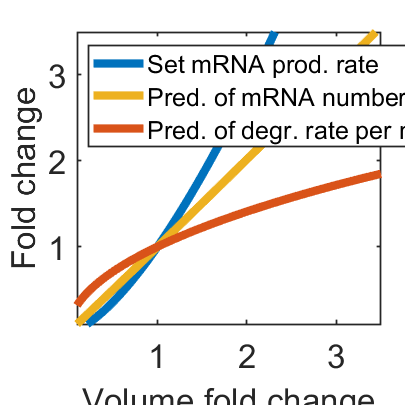


%Modify the basic parameters
k0=para_opt(1)/3;
am=para_opt(5);
ax=para_opt(6);
ay=para_opt(7);
bx=para_opt(9);
bm=para_opt(8);
Kx=para_opt(2);
Km=para_opt(4);
Vn=2.8;
Vc=37.2;
Kv=5.8262;
Ky=para_opt(3);
Xt=para_opt(10);
Yt=para_opt(11);



nperm=1000;%numebr of simulations

% Change the cell size
Vn_ori=[linspace(Vn/10,Vn,nperm/2-1),Vn,linspace(Vn,Vn*3.8,nperm/2)];
Vc_ori=[linspace(Vc/10,Vc,nperm/2-1),Vc,linspace(Vc,Vc*3.8,nperm/2)];

% Initialization of mn and mc
Vn_wt=Vn;
Vc_wt=Vc;
temp_ratio=Vn_ori/Vn_wt;
mn0=Vn*ay/am.*temp_ratio;
mc0=Vc*bx/bm.*temp_ratio;

% Keep the concentration of X and Y constant
Xn0=10000.*temp_ratio;
Xc0=50000.*temp_ratio;
Xp0=(Xt-Xn0-Xc0).*temp_ratio;
Yn0=1000.*temp_ratio;
Yp0=(Yt-Yn0).*temp_ratio;



%ODE
dt=1;
T=50000;%time duration of the simualtion

mn_tot=zeros(1,nperm);
mc_tot=zeros(1,nperm);
Xn_tot=zeros(1,nperm);
Xc_tot=zeros(1,nperm);
Xp_tot=zeros(1,nperm);
Yn_tot=zeros(1,nperm);
Yp_tot=zeros(1,nperm);
Vn_tot=zeros(1,nperm);
Vc_tot=zeros(1,nperm);

dmndt_tot=zeros(1,nperm);
dmcdt_tot=zeros(1,nperm);
dXndt_tot=zeros(1,nperm);
dXcdt_tot=zeros(1,nperm);
dXpdt_tot=zeros(1,nperm);
dYndt_tot=zeros(1,nperm);
dYpdt_tot=zeros(1,nperm);
vpro_tot=zeros(1,nperm);
vdeg_tot=zeros(1,nperm);

for j=1:nperm

    for i=1:(T/dt)
        %ODE
        if i==1
            mn=mn0(j);
            mc=mc0(j);
            Xn=Xn0(j);
            Xc=Xc0(j);
            Xp=Xp0(j);
            Yp=Yp0(j);
            Yn=Yn0(j);
        else
            mn=mn_next;
            mc=mc_next;
            Xn=Xn_next;
            Xc=Xc_next;
            Xp=Xp_next;
            Yp=Yp_next;
            Yn=Yn_next;
        end


        kn=(k0*Vn_ori(j)^1.5*1e-5)*(Xp/(Xp+Kx*Vn_ori(j)))*Vn_ori(j)*Km/(Vn_ori(j)*Km+mn)*Yp/(Yp+Ky*Vn_ori(j));
        % superliner

        dmndt=kn-am*(Yn/Vn_ori(j))*mn;
        dXndt=kn-ax*Xn;
        dXcdt=ax*Xn-bx*Xc;
        dmcdt=am*(Yn/Vn_ori(j))*mn-bm*(Xc/Vc_ori(j))*mc;
        dXpdt=bx*Xc-kn;
        dYpdt=ay*Yn-kn;
        dYndt=kn-ay*Yn;

        mn_next=mn+dmndt*dt;
        mc_next=mc+dmcdt*dt;
        Xn_next=Xn+dXndt*dt;
        Xc_next=Xc+dXcdt*dt;
        Xp_next=Xp+dXpdt*dt;
        Yp_next=Yp+dYpdt*dt;
        Yn_next=Yn+dYndt*dt;
    end

    mn_tot(j)=mn;
    mc_tot(j)=mc;
    Xn_tot(j)=Xn;
    Xc_tot(j)=Xc;
    Xp_tot(j)=Xp;
    Yn_tot(j)=Yn;
    Yp_tot(j)=Yp;
    Vn_tot(j)=Vn_ori(j);
    Vc_tot(j)=Vc_ori(j);

    dmndt_tot(j)=dmndt;
    dmcdt_tot(j)=dmcdt;
    dXndt_tot(j)=dXndt;
    dXcdt_tot(j)=dXcdt;
    dXpdt_tot(j)=dXpdt;
    dYndt_tot(j)=dYndt;
    dYpdt_tot(j)=dYpdt;
    vpro_tot(j)=kn;
    vdeg_tot(j)=bm*(Xc/Vc_ori(j))*mc;
end




%plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];
V_tot=Vn_tot+Vc_tot;
m_tot=mn_tot+mc_tot;
alpha=vdeg_tot./mc_tot;

wt=find(Vn_ori==Vn_wt);
wt=wt(1);


fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p3=plot(V_tot/V_tot(wt),vpro_tot/vpro_tot(wt),'-', ...
    "LineWidth",5, ...
    "Color",colors(1),...
    "DisplayName","Set mRNA prod. rate");
hold on
p4=plot(V_tot/V_tot(wt),m_tot/m_tot(wt),'-',...
    "LineWidth",5, ...
    "Color",colors(3),...
    "DisplayName","Pred. of mRNA number");
hold on
p5=plot(V_tot/V_tot(wt),alpha/alpha(wt),'-',...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Pred. of degr. rate per mRNA");
hold off
xlim([0.1,3.5])
ylim([0.1,3.5])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p3 p4 p5],"Interpreter","tex","FontSize",15,'Location','northwest')
xlabel('Volume fold change','interpreter','tex','FontSize',20);
ylabel('Fold change','interpreter','tex','FontSize',20);


 mRNA production rate oscillates with cell volume (Figure 3d)

%Basic paramters
load ../Parameter_determination/Basic_parameters.mat

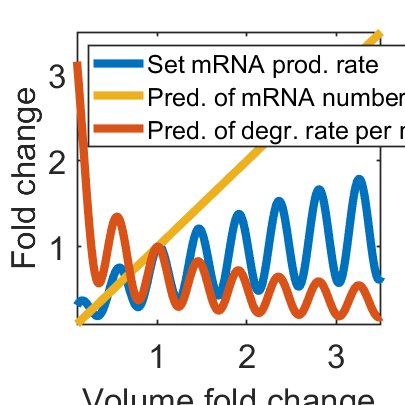


%Modify the basic parameters
k0=para_opt(1)/3;
am=para_opt(5);
ax=para_opt(6);
ay=para_opt(7);
bx=para_opt(9);
bm=para_opt(8);
Kx=para_opt(2);
Km=para_opt(4);
Vn=2.8;
Vc=37.2;
Kv=5.8262;
Ky=para_opt(3);
Xt=para_opt(10);
Yt=para_opt(11);


nperm=1000;%numebr of simulations

% Change the cell size
Vn_ori=[linspace(Vn/10,Vn,nperm/2-1),Vn,linspace(Vn,Vn*3.8,nperm/2)];
Vc_ori=[linspace(Vc/10,Vc,nperm/2-1),Vc,linspace(Vc,Vc*3.8,nperm/2)];

% Initialization of mn and mc
Vn_wt=Vn;
Vc_wt=Vc;

temp_ratio=Vn_ori/Vn_wt;
mn0=Vn*ay/am.*temp_ratio;
mc0=Vc*bx/bm.*temp_ratio;

% Keep the concentration of X and Y constant
Xn0=10000.*temp_ratio;
Xc0=50000.*temp_ratio;
Xp0=(Xt-Xn0-Xc0).*temp_ratio;
Yn0=1000.*temp_ratio;
Yp0=(Yt-Yn0).*temp_ratio;



%ODE
dt=1;
T=50000;%time duration of the simualtion


mn_tot=zeros(1,nperm);
mc_tot=zeros(1,nperm);
Xn_tot=zeros(1,nperm);
Xc_tot=zeros(1,nperm);
Xp_tot=zeros(1,nperm);
Yn_tot=zeros(1,nperm);
Yp_tot=zeros(1,nperm);
Vn_tot=zeros(1,nperm);
Vc_tot=zeros(1,nperm);

dmndt_tot=zeros(1,nperm);
dmcdt_tot=zeros(1,nperm);
dXndt_tot=zeros(1,nperm);
dXcdt_tot=zeros(1,nperm);
dXpdt_tot=zeros(1,nperm);
dYndt_tot=zeros(1,nperm);
dYpdt_tot=zeros(1,nperm);
vpro_tot=zeros(1,nperm);
vdeg_tot=zeros(1,nperm);

for j=1:nperm

    for i=1:(T/dt)
        %ODE
        if i==1
            mn=mn0(j);
            mc=mc0(j);
            Xn=Xn0(j);
            Xc=Xc0(j);
            Xp=Xp0(j);
            Yp=Yp0(j);
            Yn=Yn0(j);
        else
            mn=mn_next;
            mc=mc_next;
            Xn=Xn_next;
            Xc=Xc_next;
            Xp=Xp_next;
            Yp=Yp_next;
            Yn=Yn_next;
        end


        kn=(k0*(sin(5*Vn_ori(j))+2)*Vn_ori(j)^0.5*0.05)*(Xp/(Xp+Kx*Vn_ori(j)))*Vn_ori(j)*Km/(Vn_ori(j)*Km+mn)*Yp/(Yp+Ky*Vn_ori(j));
        % oscillation

        dmndt=kn-am*(Yn/Vn_ori(j))*mn;
        dXndt=kn-ax*Xn;
        dXcdt=ax*Xn-bx*Xc;
        dmcdt=am*(Yn/Vn_ori(j))*mn-bm*(Xc/Vc_ori(j))*mc;
        dXpdt=bx*Xc-kn;
        dYpdt=ay*Yn-kn;
        dYndt=kn-ay*Yn;

        mn_next=mn+dmndt*dt;
        mc_next=mc+dmcdt*dt;
        Xn_next=Xn+dXndt*dt;
        Xc_next=Xc+dXcdt*dt;
        Xp_next=Xp+dXpdt*dt;
        Yp_next=Yp+dYpdt*dt;
        Yn_next=Yn+dYndt*dt;
    end

    mn_tot(j)=mn;
    mc_tot(j)=mc;
    Xn_tot(j)=Xn;
    Xc_tot(j)=Xc;
    Xp_tot(j)=Xp;
    Yn_tot(j)=Yn;
    Yp_tot(j)=Yp;
    Vn_tot(j)=Vn_ori(j);
    Vc_tot(j)=Vc_ori(j);

    dmndt_tot(j)=dmndt;
    dmcdt_tot(j)=dmcdt;
    dXndt_tot(j)=dXndt;
    dXcdt_tot(j)=dXcdt;
    dXpdt_tot(j)=dXpdt;
    dYndt_tot(j)=dYndt;
    dYpdt_tot(j)=dYpdt;
    vpro_tot(j)=kn;
    vdeg_tot(j)=bm*(Xc/Vc_ori(j))*mc;
end


%plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];

V_tot=Vn_tot+Vc_tot;
m_tot=mn_tot+mc_tot;
alpha=vdeg_tot./mc_tot;

wt=find(Vn_ori==Vn_wt);
wt=wt(1);

fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p3=plot(V_tot/V_tot(wt),vpro_tot/vpro_tot(wt),'-', ...
    "LineWidth",5, ...
    "Color",colors(1),...
    "DisplayName","Set mRNA prod. rate");
hold on
p4=plot(V_tot/V_tot(wt),m_tot/m_tot(wt),'-',...
    "LineWidth",5, ...
    "Color",colors(3),...
    "DisplayName","Pred. of mRNA number");
hold on
p5=plot(V_tot/V_tot(wt),alpha/alpha(wt),'-',...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Pred. of degr. rate per mRNA");
hold off
xlim([0.1,3.5])
ylim([0.1,3.5])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p3 p4 p5],"Interpreter","tex","FontSize",15,'Location','northwest')
xlabel('Volume fold change','interpreter','tex','FontSize',20);
ylabel('Fold change','interpreter','tex','FontSize',20);